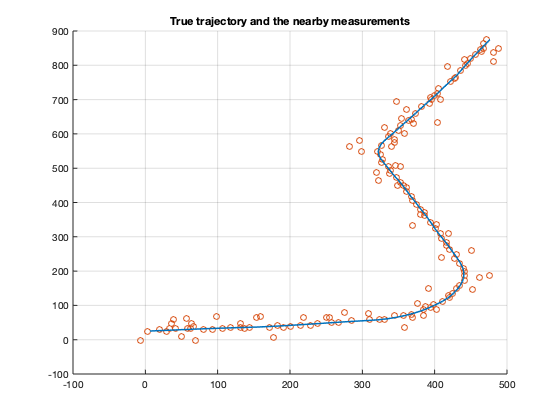

% load data
usePregen = true; % you can generate your own data if set to false
if usePregen
    load task2data.mat;
else
    K = 100;
    Ts = 2.5;
    r = 5;
    q = [0.005, 1e-6*pi]; % q(1): CV noise (effective all the time), q(2): CT noise (effective only in turns)
    init.x = [0; 0; 2; 0; 0];
    init.P = diag([25, 25, 3, 3, 0.0005].^2);
    % detection and false alarm
    PDtrue = 0.9;
    lambdatrue = 1e-4;
    [Xgt, Z, a] = simulate_atc_track(Ts, K, q, r, init, PDtrue, lambdatrue, false);
end


% plot measurements close to the trajectory
figure(1); clf; hold on; grid on;
Zplotdata = [];
plotMeasDist = 45;
for k = 1:K
   toPlot = false(size(Z{k},2),1);
   for j = 1:size(Z{k}, 2)
        v = Z{k}(:, j) - Xgt(1:2, k);
        toPlot(j) = v' * v <= plotMeasDist^2;
   end
   Zplotdata = [Zplotdata, Z{k}(:, toPlot)];
end
set(gca, 'ColorOrderIndex', 2)
scatter(Zplotdata(1,:), Zplotdata(2,:));
set(gca, 'ColorOrderIndex', 1)
plot(Xgt(1,:),Xgt(2,:), 'LineWidth',1.5);
title('True trajectory and the nearby measurements')

% play measurement movie. Remember that you can click the stop button.
figure(2); clf; grid on;
set(gcf,'Visible','on')
plotpause = 0.1; % sets a pause in between time steps if it goes to fast
minZ = min(Xgt(1:2, :), [], 2);
maxZ = max(Xgt(1:2, :), [], 2);
minZ = minZ - 0.05*(maxZ - minZ);
maxZ = maxZ + 0.05*(maxZ - minZ);
for k = 1:K
    scatter(Z{k}(1,:), Z{k}(2,:))
    title(sprintf('measurements at step %d', k))
    axis([minZ(1), maxZ(1), minZ(2), maxZ(2)])
    grid on;
    drawnow;
    pause(plotpause);
end

% Look at individual EKF-PDAs
r = 10;%...
qCV = 0.5;%...
qCT = [0.005, 0.0001];%...

lambda = 0.05;%...
PD = 0.9;%...
gateSize = 1000;%...
% choose model to tune
s = 2;

% make models
models =  cell(2,1);
models{1} = EKF(discreteCVmodel(qCV, r));
models{2} = EKF(discreteCTmodel(qCT, r));

tracker =  cell(2,1);
tracker{1} = PDAF(models{1}, lambda, PD, gateSize);
tracker{2} = PDAF(models{2}, lambda, PD, gateSize);

% % % % allocate
xbar = zeros(5, K);
Pbar = zeros(5, 5, K);
xhat = zeros(5, K);
Phat = zeros(5, 5, K);
NEES = zeros(K, 1);
NEESpos = zeros(K, 1);
NEESvel = zeros(K, 1);

% initialize filter
xbar(:, 1) = [0; 0; 2; 0; 0];
Pbar(:, : ,1) = diag([25, 25, 3, 3, 0.0005].^2);

% filter
for k = 1:K
    [xhat(:, k), Phat(:, :, k)] = tracker{s}.update(cell2mat(Z(k,:)), xbar(:,k), Pbar(:,:,k));%... update
    NEES(k) = ((xhat(1:4,k)-xbar(1:4,k))')*inv(Pbar(1:4,1:4,k))*(xhat(1:4,k) - xbar(1:4,k));%... 
    NEESpos(k) = ((xhat(1:2,k)-xbar(1:2,k))')*inv(Pbar(1:2,1:2,k))*(xhat(1:2,k) - xbar(1:2,k));%...
    NEESvel(k) = ((xhat(3:4,k)-xbar(3:4,k))')*inv(Pbar(3:4,3:4,k))*(xhat(3:4,k) - xbar(3:4,k));%...
    if k < K
        [xbar(:, k+1), Pbar(:, :, k+1)] = tracker{s}.predict(xhat(:,k), Phat(:,:,k), Ts);%... predict
    end
end

% errors
poserr = sqrt(sum((xhat(1:2,:) - Xgt(1:2,:)).^2, 1));
posRMSE = sqrt(mean(poserr.^2));
velerr = sqrt(sum((xhat(3:4, :) - Xgt(3:4, :)).^2, 1));
velRMSE = sqrt(mean(velerr.^2));

% consistency
chi2inv([0.025, 0.975], K*2)/K

ans =     1.6273    2.4106


ANEESpos = mean(NEESpos)

ANEESpos = 0.3471

ANEESvel = mean(NEESvel)

ANEESvel = 0.2288


chi2inv([0.025, 0.975], K*4)/K

ans =     3.4648    4.5731


ANEES = mean(NEES)

ANEES = 0.3471

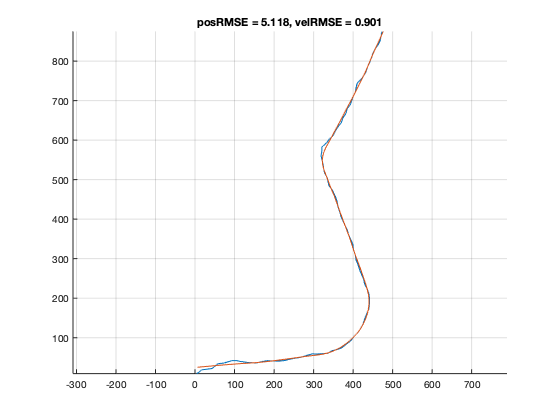


% plot
figure(3); clf; hold on; grid on;
plot(xhat(1,:), xhat(2,:));
plot(Xgt(1, :), Xgt(2, :))
axis('equal')
%scatter(Z(1,:), Z(2, :));
title(sprintf('posRMSE = %.3f, velRMSE = %.3f',posRMSE, velRMSE))

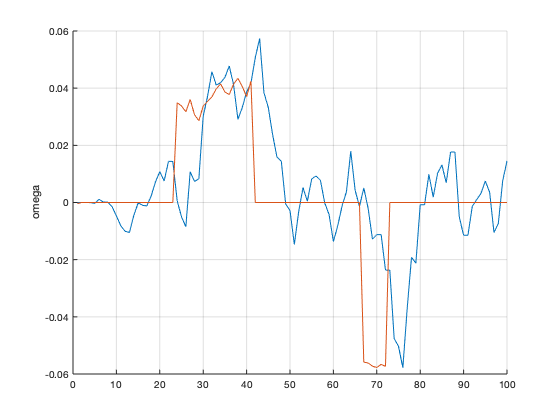


figure(4); clf; hold on; grid on;
plot(xhat(5,:))
plot(Xgt(5,:))
ylabel('omega')

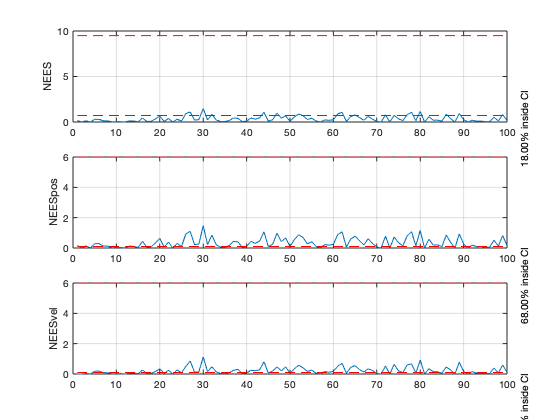


figure(5); clf;
subplot(3,1,1);
plot(NEES); grid on; hold on;
ylabel('NEES');
ciNEES = chi2inv([0.05, 0.95], 4);
inCI = sum((NEES >= ciNEES(1)) .* (NEES <= ciNEES(2)))/K * 100;
plot([1,K], repmat(ciNEES',[1,2])','r--')
text(104, -5, sprintf('%.2f%% inside CI', inCI),'Rotation',90);

subplot(3,1,2);
plot(NEESpos); grid on; hold on;
ylabel('NEESpos');
ciNEES = chi2inv([0.05, 0.95], 2);
inCI = sum((NEESpos >= ciNEES(1)) .* (NEESpos <= ciNEES(2)))/K * 100;
plot([1,K], repmat(ciNEES',[1,2])','r--')
text(104, -5, sprintf('%.2f%% inside CI', inCI),'Rotation',90);

subplot(3,1,3);
plot(NEESvel); grid on; hold on;
ylabel('NEESvel');
ciNEES = chi2inv([0.05, 0.95], 2);
inCI = sum((NEESvel >= ciNEES(1)) .* (NEESvel <= ciNEES(2)))/K * 100;
plot([1,K], repmat(ciNEES',[1,2])','r--')
text(104, -5, sprintf('%.2f%% inside CI', inCI),'Rotation',90);

% IMM-PDA

% sensor 
r = 1.9;%...
lambda = 0.01;%...
PD = 0.95;%...
gateSize = 25;%...

% dynamic models
qCV = 0.02;%...
qCT = [0.005, 0.0001];%...
x0 = [6, 25, 0, 0, 0]';%...
P0 = diag([25, 25, 3, 3, 0.0005].^2);%...

% markov chain (you are free to parametrize this in another way)
PI11 = 0.85;%...
PI22 = 0.65;%... 
p10 = 0.80;%... 

PI = [PI11, (1 - PI22); (1 - PI11), PI22]; assert(all(sum(PI, 1) == [1, 1]),'columns of PI must sum to 1')
sprobs0 = [p10; (1 - p10)]; assert(sum(sprobs0) == 1, 'initial mode probabilities must sum to 1');

% make model
models =  cell(2,1);
models{1} = EKF(discreteCVmodel(qCV, r));
models{2} = EKF(discreteCTmodel(qCT, r));
imm = IMM(models, PI);
tracker = IMMPDAF(imm, lambda, PD, gateSize);

% allocate
xbar = zeros(5, 2, K);
Pbar = zeros(5, 5, 2, K);
probbar = zeros(2, K);
xhat = zeros(5, 2, K);
xest = zeros(5, K);
Pest = zeros(5, 5, K);
Phat = zeros(5, 5, 2, K);
probhat = zeros(2, K);
NEES = zeros(K, 1);
NEESpos = zeros(K, 1);
NEESvel = zeros(K, 1);


% initialize
xbar(:, :, 1) = repmat(x0, [1, 2]);
Pbar(:, : ,:, 1) = repmat(P0,[1,1,2]);
probbar(:, 1) = sprobs0;

% filter
for k=1:100
    [probhat(:, k), xhat(:, :, k), Phat(:, :, :, k)] = tracker.update(cell2mat(Z(k,:)), probbar(:,k), xbar(:,:,k), Pbar(:,:,:,k));%... update
    [xest(:, k), Pest(:, :, k)] = reduceGaussMix(probbar(:, k), xbar(:, :, k), Pbar(:, :, :, k));%... total state mean and cov
    NEES(k) = ((xhat(1:4,k)-xbar(1:4,k))')/Pbar(1:4,1:4,k)*(xhat(1:4,k) - xbar(1:4,k));%... 
    NEESpos(k) = ((xhat(1:2,k)-xbar(1:2,k))')*inv(Pbar(1:2,1:2,k))*(xhat(1:2,k) - xbar(1:2,k));%...
    NEESvel(k) = ((xhat(3:4,k)-xbar(3:4,k))')*inv(Pbar(3:4,3:4,k))*(xhat(3:4,k) - xbar(3:4,k));%...
    if k < 100
        [probbar(:, k+1), xbar(:, :, k+1), Pbar(:, :, :, k+1)] = tracker.predict(probhat(:,k), xhat(:,:,k), Phat(:,:,:,k), Ts);%... predict
    end
end

% errors
poserr = sqrt(sum((xest(1:2,:) - Xgt(1:2,:)).^2, 1));
posRMSE = sqrt(mean(poserr.^2));

 % not true RMSE (which is over monte carlo simulations)
velerr = sqrt(sum((xest(3:4, :) - Xgt(3:4, :)).^2, 1));
velRMSE = sqrt(mean(velerr.^2)); % not true RMSE (which is over monte carlo simulations)
peakPosDeviation = max(poserr);
peakVelDeviation = max(velerr);

% consistency
CI2K = chi2inv([0.025, 0.975], K*2)/K

CI2K =     1.6273    2.4106


ANEESpos = mean(NEESpos)

ANEESpos = 2.3631

ANEESvel = mean(NEESvel)

ANEESvel = 1.6362


CI4K = chi2inv([0.025, 0.975], K*4)/K

CI4K =     3.4648    4.5731


ANEES = mean(NEES)

ANEES = 2.3631

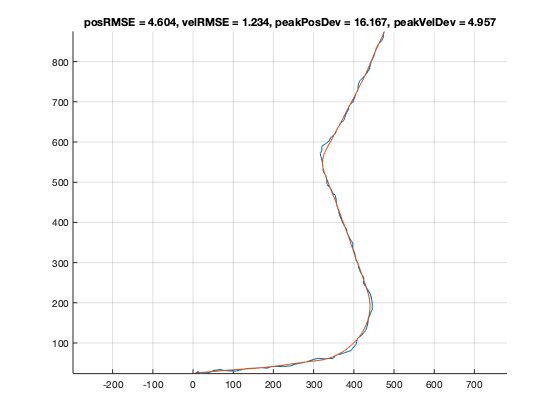


% plot
figure(6); clf; hold on; grid on;
plot(xest(1,:), xest(2,:));
plot(Xgt(1,:), Xgt(2, :));
axis('equal')
title(sprintf('posRMSE = %.3f, velRMSE = %.3f, peakPosDev = %.3f, peakVelDev = %.3f',posRMSE, velRMSE, peakPosDeviation, peakVelDeviation))

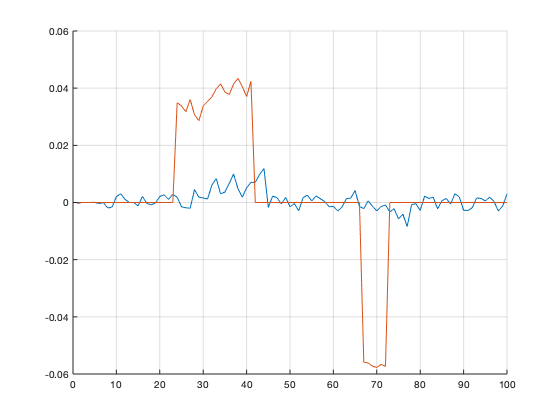


figure(7); clf; hold on; grid on;
plot(xest(5,:))
plot(Xgt(5,:))

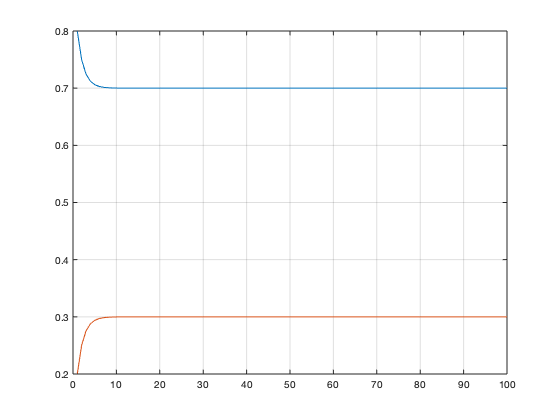


figure(8); clf;
plot(probhat');
grid on;

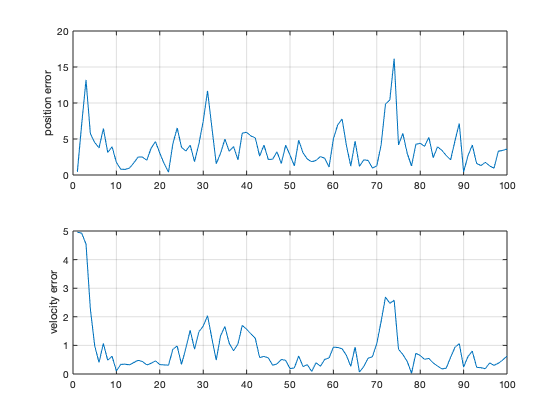


figure(9); clf;
subplot(2,1,1); 
plot(poserr); grid on;
ylabel('position error')
subplot(2,1,2);
plot(velerr); grid on;
ylabel('velocity error')

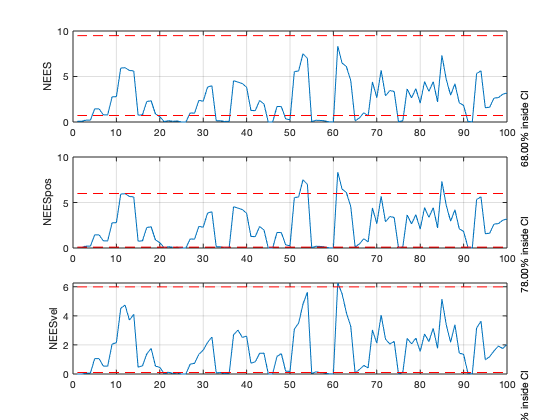


figure(10); clf;
subplot(3,1,1);
plot(NEES); grid on; hold on;
ylabel('NEES');
ciNEES = chi2inv([0.05, 0.95], 4);
inCI = sum((NEES >= ciNEES(1)) .* (NEES <= ciNEES(2)))/K * 100;
plot([1,K], repmat(ciNEES',[1,2])','r--')
text(104, -5, sprintf('%.2f%% inside CI', inCI),'Rotation',90);

subplot(3,1,2);
plot(NEESpos); grid on; hold on;
ylabel('NEESpos');
ciNEES = chi2inv([0.05, 0.95], 2);
inCI = sum((NEESpos >= ciNEES(1)) .* (NEESpos <= ciNEES(2)))/K * 100;
plot([1,K], repmat(ciNEES',[1,2])','r--')
text(104, -5, sprintf('%.2f%% inside CI', inCI),'Rotation',90);

subplot(3,1,3);
plot(NEESvel); grid on; hold on;
ylabel('NEESvel');
ciNEES = chi2inv([0.05, 0.95], 2);
inCI = sum((NEESvel >= ciNEES(1)) .* (NEESvel <= ciNEES(2)))/K * 100;
plot([1,K], repmat(ciNEES',[1,2])','r--')
text(104, -5, sprintf('%.2f%% inside CI', inCI),'Rotation',90);

%estimation "movie"
mTL = 0.2; % maximum transparancy (between 0 and 1);
plotpause = 1; % lenght to pause between time steps;
plotRange = 2:K % the range to go through
N = 50; % number of points to use for ellipse;

%k = 31; assert(all([k > 1, k <= K]), 'K must be in proper range')
figure(11); clf; grid on; hold on; axis equal;
set(gcf,'Visible','on')
co = get(gca, 'colorOrder');
minAx = min(cell2mat(Z'));
maxAx = max(cell2mat(Z'));
thetas = (0:N)*2*pi/N;
for k = plotRange
    % tracker
    subplot(1,2,1);
    cla; grid on; hold on; axis equal;
    title(sprintf('time step %d', k));
    gated = tracker.gate(Z{k}, probbar(:, k), xbar(:, :, k), Pbar(:, :, :, k));
    minG = 1e20 * ones(2,1);
    maxG = zeros(2,1);
    [skupd, xkupd, Pkupd] = tracker.conditionalUpdate(Z{k}(:, gated), probbar(:, k), xbar(:, :, k), Pbar(:, :, :, k));
    beta = tracker.associationProbabilities(Z{k}(:, gated), probbar(:, k), xbar(:, :, k), Pbar(:, :, :, k));
    for s = 1:2
        plot(squeeze(xhat(1, s, 1:(k-1))), squeeze(xhat(2, s, 1:(k-1)))','Color', co(s,:));
        axis([minAx(1), maxAx(1), minAx(2), maxAx(2)])
        for j = 1:size(xkupd, 3)
            csj = mTL * co(s, :) + (1 - mTL) * (beta(j)*skupd(s, j)*co(s, :) + (1 - beta(j)*skupd(s, j)) * ones(1, 3)); % transparancy
            pl = plot([squeeze(xhat(1, s, k-1)); xkupd(1, s, j)], [squeeze(xhat(2, s, k-1)); xkupd(2, s, j)], '--', 'Color', csj);
            axis([minAx(1), maxAx(1), minAx(2), maxAx(2)])
            %alpha(pl, beta(j)*skupd(s, j));
            drawnow;
            covEllData = chol(Pkupd(1:2,1:2, s, j))' * [cos(thetas); sin(thetas)] + xkupd(1:2, s, j);
            pl = plot(covEllData(1, :), covEllData(2, :), '--', 'Color', csj);
        end
        
        [vk, Sk] = imm.modeFilters{s}.innovation([0,0], squeeze(xbar(:, s, k)), squeeze(Pbar(:, :, s, k)));
        gateData = chol(Sk)' * [cos(thetas); sin(thetas)] * sqrt(tracker.gateSize) + squeeze(xbar(1:2, s, k));
        plot(gateData(1, :),gateData(2, :), '.--', 'Color', co(s,:))
        scatter(Z{k}(1, :), Z{k}(2, :), 'rx')
        if a(k) > 0
            scatter(Z{k}(1, a(k)), Z{k}(2, a(k)), 'gx')
        end
        minGs = min(gateData, [], 2);
        minG = minGs .* (minGs < minG) + minG .* (minG < minGs);
        maxGs = max(gateData, [], 2);
        maxG = maxGs .* (maxGs > maxG) + maxG .* (maxG > maxGs);
        
    end
    scale = 1;
    minAx = minG - scale * (maxG - minG);
    maxAx = maxG + scale * (maxG - minG);
    axis([minAx(1), maxAx(1), minAx(2), maxAx(2)])
    %legend()
    
    % mode probabilities
    subplot(1,2,2)
    cla; grid on; hold on;
    for s = 1:2
        plot(probhat(s, 1:(k - 1)), 'Color', co(s, :));
        for j = 1:size(xkupd, 3)
            csj = mTL * co(s, :) + (1 - mTL) * (beta(j)*skupd(s, j)*co(s, :) + (1 - beta(j)*skupd(s, j)) * ones(1, 3)); % transparancy
            plot([k-1, k], [probhat(s, k-1), skupd(s, j)], '--', 'color', csj)
        end
    end
    axis([1, plotRange(end), 0, 1])
    drawnow;
    pause(plotpause)
end